# **Supplementary Materials**

# **Cellular communication in lichens is defined by interwoven metabolic architectures**

## Cristal Zuñiga, Geng Yu, Chien-Ting Li, Mahmoud M. Al-Bassam, Ting-Ting Li, Livia S. Zaramela, Michael Guarnieri, Michael J. Betenbaugh, Karsten Zengler*

**University of California San Diego, 11/6/2018**

## Example code

%Loading individual and community models
load('C:\Users\Cristal\Documents\MATLAB\Chlorella1\Community\Chlorella\iCZ-Cv(843)-Sc(904).mat')
load('combinedModel_GeneAnalysis8.11.2017_ReanalysisFail.mat', 'modelSc2')
load('iCZ-CvSc_BOF_GeneEssentiallity_glucoseExpData6.20.2017.mat', 'CoModels')
load('iCZ-CvSc_BOF_GeneEssentiallity_glucoseExpData6.20.2017.mat', 'ModelPA')
%initCobraToolbox;

## **Metabolic exchange and RNA-seq data**

## **Interwoven metabolic interactions in the synthetic lichen (Figure 1). **

**(A) **The panels show the course of growth of individual microorganisms and the lichen community using the culture medium BBM and BBM+2% glucose. **(B) **Predicted flux distribution of metabolites from the extracellular space to the community-members. NO3, glucose, oxygen, and CO2 fluxes (mmol/gDW/h) are split depending on the metabolic capabilities of the community-members. The grey arrows indicate mass coming from the Shared Metabolite Pool (SMP), while the intracellular fluxes of the photobiont and mycobiont are set in green and yellow, respectively. **(C)** Complete metabolic exchange. Error bars represent the predicted flux variability, while growth predictions reach at least 95% of the maximum growth rate. The green panel encloses metabolites produced by the photobiont. The red panel contains metabolites provided by the mycobiont. Metabolites in the pearl-white panel are supplied (e.g. culture medium compounds) to the system. (**D)** Differential expression results obtained during the photobiont growth under monoculture and coculture conditions. Up and down regulated genes were determined using t-test and a cut off P=0.05.  

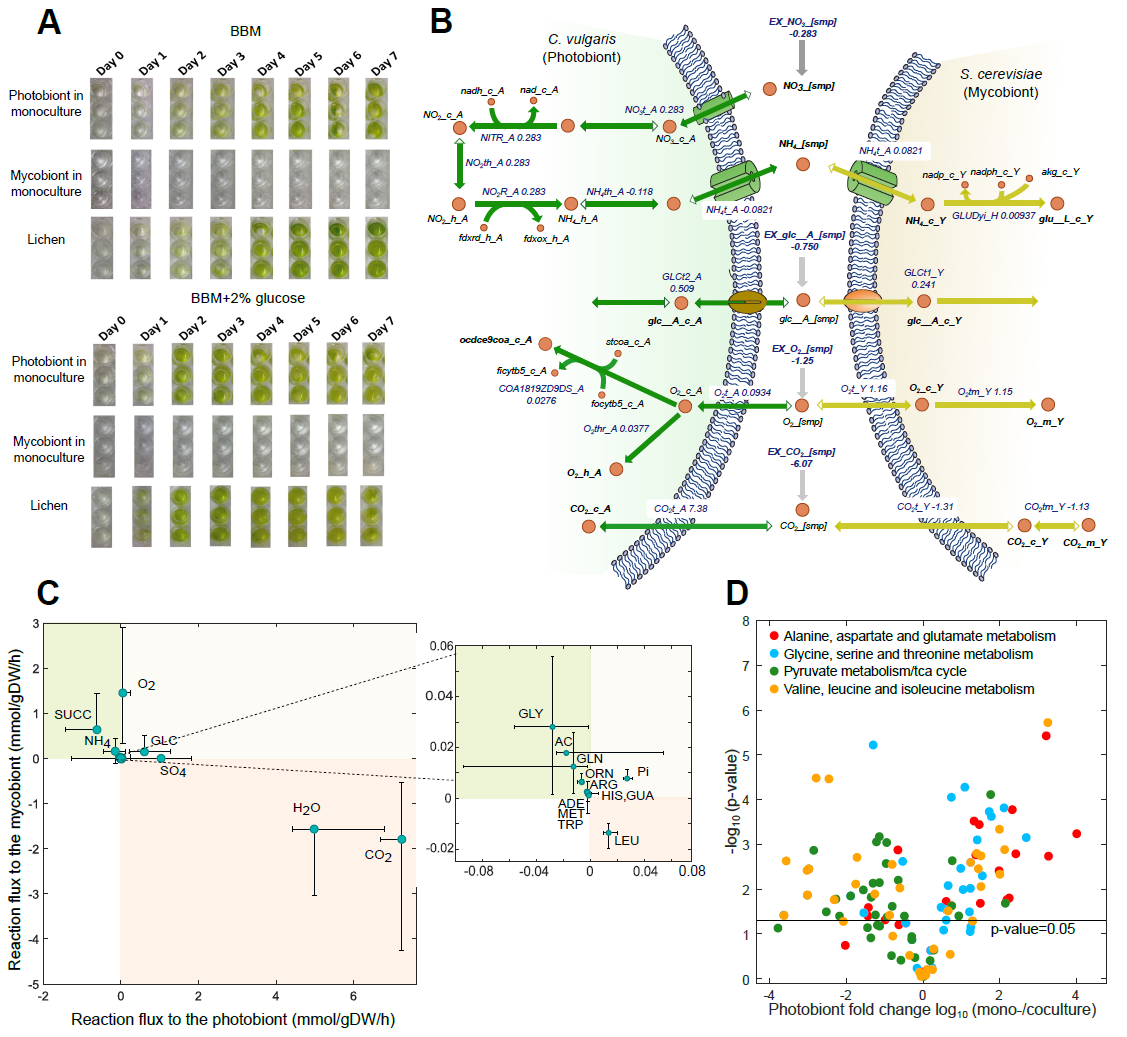

model=mergeModelm; solutionLna=optimizeCbModel(model,'max','one');
[model,SPM_rxns,SPM_D1, Un_D, Un_A] = sharedPoolCM(model,1); 

FBAsolution1 = struct with fields:
           x: [3863×1 double]
           f: 0.0722
           y: [2964×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.1390


Ind(1)=strmatch('ACt_A', model.rxns); 
Ind(2)=strmatch('ACt2r_D', model.rxns); 
Ind(3)=strmatch('ACtr_D', model.rxns); 
solutionLna.x(Ind); 
SPM_D1(2,:) = []; 
SPM_D1.Flux(1) = solutionLna.x(Ind(2)); 
Ind(1)=strmatch('SO4ti_D', model.rxns); 
Ind(2)=strmatch('SO4NA1t_A', model.rxns); 
Ind(3)=strmatch('SO4ti_D', model.rxns);
Ind(4)=strmatch('SO4t_A', model.rxns); 
solutionLna.x(Ind); 
SPM_D1(18,:) = []; 


Target_Rxns={}; 
Target_Rxns=vertcat(SPM_D1.Name,SPM_D1.Full_Name,Un_D.Name,Un_A.Name); 
[minFlux,maxFlux,Vmin,Vmax] = fluxVariability(model,95,'max',Target_Rxns); 
Solution=optimizeCbModel(model) 
Ind=find(model.c); 
Model_sampling=changeRxnBounds(model,model.rxns(Ind,1),Solution.x(Ind,1)*0.95,'l'); 
[sampleStructOutH, mixedFracH] = gpSampler(Model_sampling,15000); 
sampling{1,1}=sampleStructOutH.points; 
for i=1:length(model.rxns)
        M=median(sampling{1,1}(i,:));
        if M>10^-10
            A=sampling{1,1}(i,:);
            D=all((A(1,1)==A(:,1)));
            if isempty(D)
                 [n,bins] = hist(sampling{1,1}(i,:),50);
                 [pks,locs] = findpeaks(smooth(bins,n')/sum(n'));
                 if ~isempty(locs)
                     if length(locs)>1
                     Sam_MdT{i,1}=bins(locs(1));
                     else
                       Sam_MdT{i,1}=bins(locs);  
                     end
                 else
                     Sam_MdT{i,1}=0;
                 end
            else
                Sam_MdT{i,1}=A(1,1);
            end
        else
            Sam_MdT{i,1}=0;
        end
end

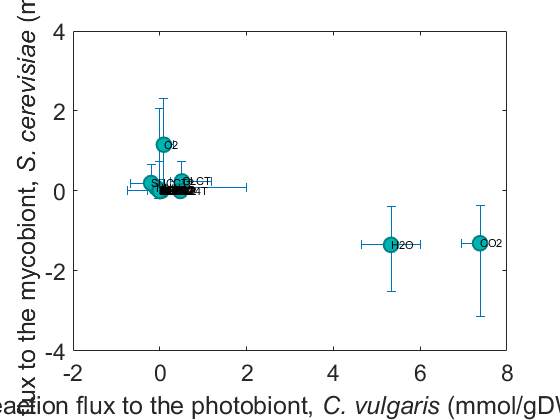


SamMdt_min=min(sampling{1,1},[],2); 
SamMdt_max=max(sampling{1,1},[],2); 
SamMdt_min(find(abs(SamMdt_min)<1e-10))=0; 
SamMdt_max(find(abs(SamMdt_max)<1e-10))=0; 
for i=1:length(Target_Rxns) 
    ind=strmatch(Target_Rxns{i},model.rxns,'exact'); 
    Target_Rxns{i,2}=minFlux(i); 
    Target_Rxns{i,3}=maxFlux(i); 
    Target_Rxns{i,4}=SamMdt_min(ind); 
    Target_Rxns{i,5}=SamMdt_max(ind); 
    Target_Rxns{i,6}=Sam_MdT{ind}; 
    if abs(Target_Rxns{i,4})>3 
        Target_Rxns{i,4}=Target_Rxns{i,6}; 
    end 
    if abs(Target_Rxns{i,4})>3 
        Target_Rxns{i,4}=(abs(Target_Rxns{i,4})-abs(Target_Rxns{i,5}))/2; 
    end 
    if abs(Target_Rxns{i,4})>3 
        Target_Rxns{i,4}=0; 
    end 
    if abs(Target_Rxns{i,5})>3 
        Target_Rxns{i,5}=Target_Rxns{i,6}; 
    end 
    if abs(Target_Rxns{i,5})>3 
        Target_Rxns{i,5}=(abs(Target_Rxns{i,4})-abs(Target_Rxns{i,5}))/2; 
    end 
    if abs(Target_Rxns{i,5})>3 
        Target_Rxns{i,5}=0; 
    end 
end 
SPMss={}; 
for i=1:height(SPM_D1) 
    String=SPM_D1.Name(i,1); 
    SPMss{i,1}=upper(String{1,1}(1:end-3)); 
end 
b=SPMss; 
DAta=SPM_D1.Rxn; 
DAta2=SPM_D1.Flux; 
yneg = transpose(cell2mat(Target_Rxns(1:length(SPM_D1.Name),4))); 
ypos = transpose(cell2mat(Target_Rxns(1:length(SPM_D1.Name),5))); 
xneg = transpose(cell2mat(Target_Rxns(length(SPM_D1.Name)+1:2*length(SPM_D1.Name),4))); 
xpos = transpose(cell2mat(Target_Rxns(length(SPM_D1.Name)+1:2*length(SPM_D1.Name),5))); 
errorbar(DAta,DAta2,yneg,ypos,xneg,xpos,'o') 
hold on 
plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],... 
    'MarkerFaceColor',[0 .7 .7],... 
    'LineWidth',1.5) 
set(gca,'FontSize',17); 
xlabel('Reaction flux to the photobiont, {\itC. vulgaris} (mmol/gDW/h)') 
ylabel('Reaction flux to the mycobiont, {\itS. cerevisiae} (mmol/gDW/h)') 
text(DAta,DAta2,b,'FontSize',8) 

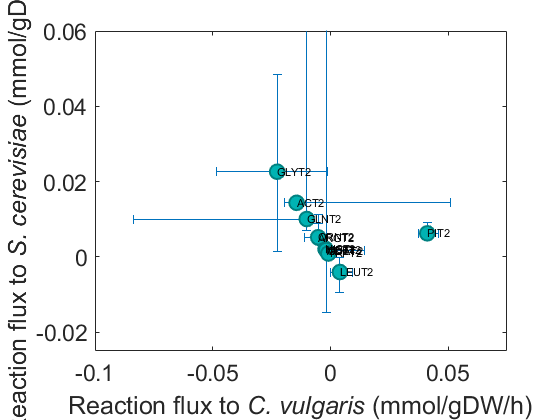

%Deeper view SPM plot figure %

figure
% plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],... 
%     'MarkerFaceColor',[0 .7 .7],... 
%     'LineWidth',1.5) 
axis([-0.05 0.05 -0.005 0.04]) 
yneg = transpose(cell2mat(Target_Rxns(1:length(SPM_D1.Name),4)))/10; 
ypos = transpose(cell2mat(Target_Rxns(1:length(SPM_D1.Name),5)))/10; 
xneg = transpose(cell2mat(Target_Rxns(length(SPM_D1.Name)+1:2*length(SPM_D1.Name),4)))/10; 
xpos = transpose(cell2mat(Target_Rxns(length(SPM_D1.Name)+1:2*length(SPM_D1.Name),5)))/10; 
errorbar(DAta,DAta2,yneg,ypos,xneg,xpos,'o') 
axis([-0.1 0.075 -0.025 0.06]);
hold on 
plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],... 
    'MarkerFaceColor',[0 .7 .7],... 
    'LineWidth',1.5) 
set(gca,'FontSize',17); 
xlabel('Reaction flux to {\itC. vulgaris} (mmol/gDW/h)') 
ylabel('Reaction flux to {\itS. cerevisiae} (mmol/gDW/h)') 
text(DAta,DAta2,b,'FontSize',8)

%RNA seq analysis

Subsystems={'Alanine, aspartate and glutamate metabolism','Glycine, serine and threonine metabolism','Pyruvate metabolism/tca cycle','Valine, leucine and isoleucine metabolism'};
  C = {'Red','DeepSkyBlue','ForestGreen','Orange','Maroon','DarkGray'};
  
load('C:\Users\Cristal\Documents\MATLAB\Chlorella1\Community\Chlorella\ChlorellaExp1.mat')
load('C:\Users\Cristal\Documents\MATLAB\Chlorella1\Community\Chlorella\YeastExp1.mat')
  

figure  
subplot(2,1,1)
 for i=1:length(Subsystems)
    index=strmatch(Subsystems{i},ChlorellaExp1(:,5),'exact');
    pvalues = mattest(cell2mat(ChlorellaExp1(index,2:4)), cell2mat(ChlorellaExp1(index,6:8)));
    plot(log2(cell2mat(ChlorellaExp1(index,9))./cell2mat(ChlorellaExp1(index,10))), -log10(pvalues),'o','MarkerFaceColor',rgb(C{i}),'MarkerEdgeColor','none')
    hold on
 end     
x = [-6 6]; y = [1.3 1.3]; pl = line(x,y); pl.Color='black'; %Line
legend(Subsystems); legend boxoff
axis([-6 6 -0.1 8])
xlabel('Fold change photobiont log_1_0(mono-/coculture)'); ylabel('-log_1_0(p-value)'); %title('Coculture Day 4 / Monoculture Day 4')

Subsystems={'Alanine, aspartate and glutamate metabolism','Cysteine and methionine metabolism','Glycine, serine and threonine metabolism','Pyruvate metabolism/tca cycle','Valine, leucine and isoleucine metabolism'};
  C = {'Red','DarkGray','DeepSkyBlue','ForestGreen','Orange','Maroon'}

C = 1×6 cell array
    {'Red'}    {'DarkGray'}    {'DeepSkyBlue'}    {'ForestGreen'}    {'Orange'}    {'Maroon'}


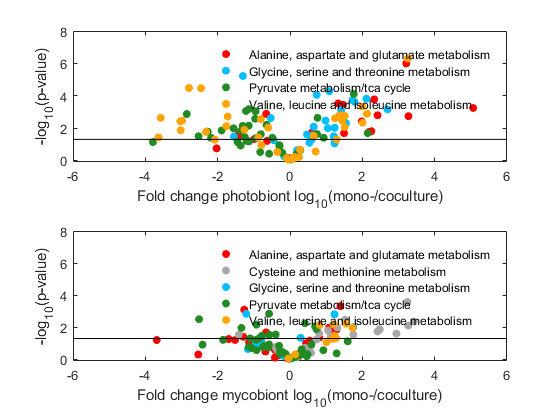

subplot(2,1,2)
 for i=1:length(Subsystems)
    index=strmatch(Subsystems{i},YeastExp1(:,5),'exact');
    pvalues = mattest(cell2mat(YeastExp1(index,2:4)), cell2mat(YeastExp1(index,6:8)));
    plot(log2(cell2mat(YeastExp1(index,9))./cell2mat(YeastExp1(index,10))), -log10(pvalues),'o','MarkerFaceColor',rgb(C{i}),'MarkerEdgeColor','none')
    hold on
 end  
x = [-6 6]; y = [1.3 1.3]; pl = line(x,y); pl.Color='black'; %Line
legend(Subsystems); legend boxoff
axis([-6 6 -0.1 8])
xlabel('Fold change mycobiont log_1_0(mono-/coculture)'); ylabel('-log_1_0(p-value)'); %title('Coculture Day 4 / Monoculture Day 4')

## **The community interactions depend on culture conditions (Figure 2)**

Predicted growth rates while varying O2 and glucose uptake rates of the mycobiont **(A)** and photobiont **(B)** in the lichen. **(C)** Overall bionts growth rate is given by the sum of **A** and **B**. **(D)** Growth rates at various glucose uptake rates were experimentally validated (solid lines). Predictions are shown in dotted lines and were performed by using physiologically determined glucose uptake rates of 0.14±0.01 - 0.38±0.04 mmol/gDW/h. Photobiont experimental growth rates (green) were not significantly different (t-test, P=0.5); mycobiont growth rates (yellow) were statistically different (t-test, P=0.0001) as predicted. **(E)**Mycobiont predicted growth rate while varying the NH4 and NO3uptake rates. **(F)** Photobiont predicted growth rates showed that high NH4 uptake rates affected its growth. **(G)** Bionts overall growth rate, the numbers delimit the type of interaction (fig S1A). (*) indicates interactions experimentally validated.** (H)** Experimental (bar plots) and predicted (dots) growth rates at different NO3 and NH4 concentrations for the mycobiont (yellow) and photobiont (green).

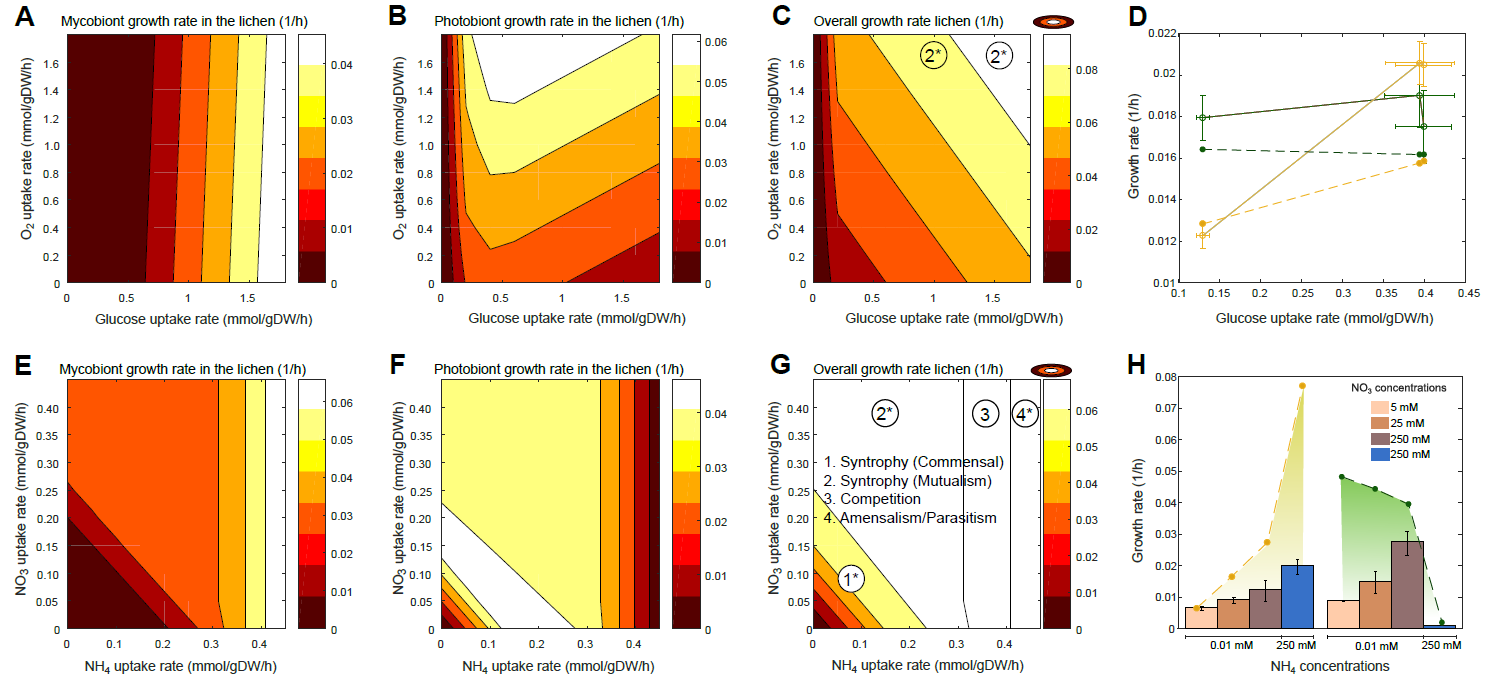

## **Stability analysis of the lichen partners while varying consumption rates (fig. S4)**

Optimal growth rates of the synthetic lichen community in standard conditions. The diagonal of the scatter matrix shows the robustness analysis while flux through glucose, NO3, NH4, and O2uptake rates were varied. The overall growth rate is presented in color blue, the growth rates of photobiont and mycobiont in green and yellow, respectively. Row **(A)** presents the phenotypic phase planes for growth with varying glucose uptake rate together with NO3, O2, and NH4. **(B)**Phenotypic phase planes of alternating uptake rates of NO3 with O2and NH4. **(C)** phenotypic phase plane varying O2 and NH4. **(D)** Phenotypic phase plane while varying NH4.  

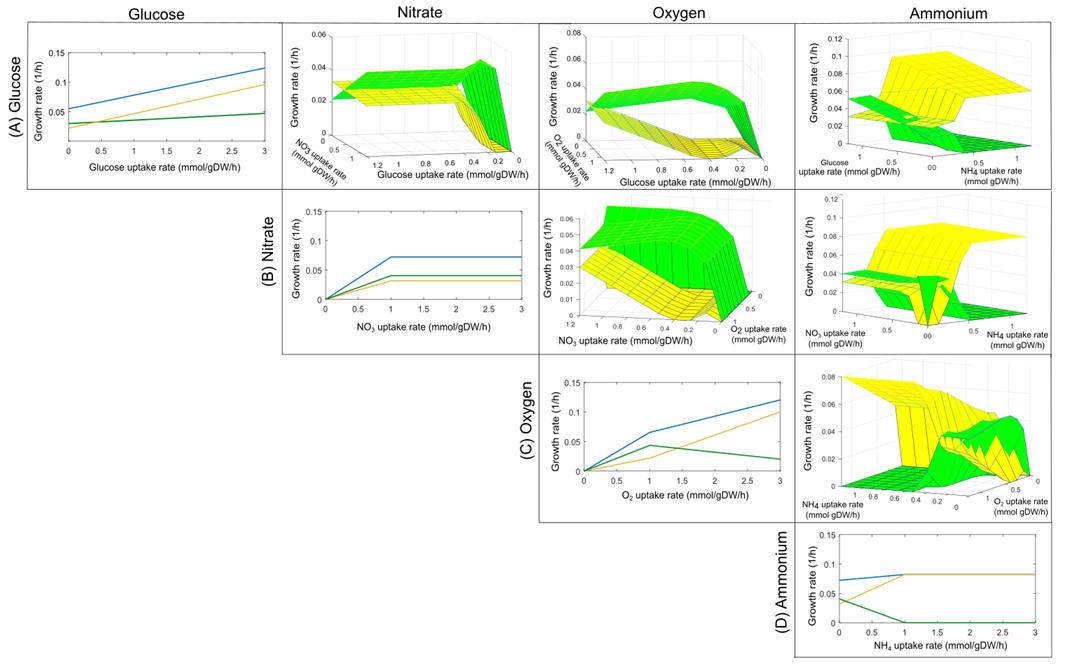

mayaAuto=[];x=[];mayaAuto1=[];mayaAuto2=[];y=[];
model=mergeModelm;
BOFs=find(model.c);
    solutionLna = optimizeCbModel(model,'max','one');
    cont=0;cont0=0;
    for i=1:10
        cont0=cont+1;
        for j=1:10
            valor=(i-1)/5;
            valor1=(j-1)/5;
            model=changeRxnBounds(model,{'EX_glc__A_[smp]','EX_o2_[smp]'},[-valor -valor1],'l');
            solutionLna = optimizeCbModel(model);
                if solutionLna.f~=0
                  mayaAuto(i,j)=solutionLna.f;  
                    cont=cont+1;
                mayaAuto1(i,j)=solutionLna.x(BOFs(1,1));
                mayaAuto2(i,j)=solutionLna.x(BOFs(2,1));
                end
        x(i)=valor;
        y(j)=valor1;
        end
    cont=0;
    end
    %Pair-wise robustness analysis
     smayaAuto=[];sx=[];smayaAuto1=[];smayaAuto2=[];sy=[];
model=mergeModelm;
    solutionLna = optimizeCbModel(model,'max','one');
    cont=0;cont0=0;
    for i=1:100
        cont0=cont+1;
        for j=1:100
            valor=(i-1)/200;
            valor1=(j-1)/200;
            model=changeRxnBounds(model,{'EX_no3_[smp]','EX_nh4_[smp]'},[-valor -valor1],'l');
            solutionLna = optimizeCbModel(model);
                if solutionLna.f~=0
                  smayaAuto(i,j)=solutionLna.f;  
                    cont=cont+1;
                smayaAuto1(i,j)=solutionLna.x(BOFs(1,1));
                smayaAuto2(i,j)=solutionLna.x(BOFs(2,1));
                smayaAuto3(i,j)=(smayaAuto1(i,j)/smayaAuto2(i,j));%*smayaAuto;
                end
        sx(i)=valor;
        sy(j)=valor1;
        end
    cont=0;
    end
    

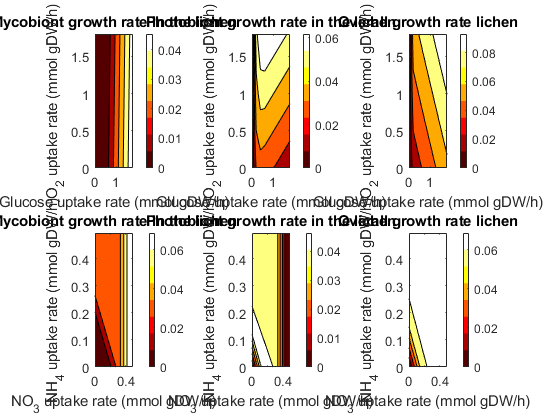

    figure
ax2 = subplot(2,3,1);
contourf(x,y,mayaAuto1,5)
colormap(ax2,hot(8))
 title(ax2,'Mycobiont growth rate in the lichen'); 
 ylabel('O_2 uptake rate (mmol gDW/h)');
 xlabel('Glucose uptake rate (mmol gDW/h)');
 colorbar

 ax3 = subplot(2,3,2);
contourf(x,y,mayaAuto2,5)
colormap(ax3,hot(8))
xlabel('Glucose uptake rate (mmol gDW/h)');
 ylabel('O_2 uptake rate (mmol gDW/h)');
 title(ax3,'Photobiont growth rate in the lichen'); 
  colorbar
 
 ax1 = subplot(2,3,3);
contourf(x,y,mayaAuto,5)
colormap(ax1,hot(8))
 ylabel('O_2 uptake rate (mmol gDW/h)');
 xlabel('Glucose uptake rate (mmol gDW/h)');
title(ax1,'Overall growth rate lichen');
 colorbar


ax2 = subplot(2,3,4);
contourf(sx,sy,smayaAuto1,5)
colormap(ax2,hot(8))
 title(ax2,'Mycobiont growth rate in the lichen'); 
 ylabel('NH_4 uptake rate (mmol gDW/h)');
 xlabel('NO_3 uptake rate (mmol gDW/h)');
 colorbar

 ax3 = subplot(2,3,5);
contourf(sx,sy,smayaAuto2,5)
colormap(ax3,hot(8))
xlabel('NO_3 uptake rate (mmol gDW/h)');
 ylabel('NH_4 uptake rate (mmol gDW/h)');
 title(ax3,'Photobiont growth rate in the lichen');
 colorbar
 
 ax1 = subplot(2,3,6);
contourf(sx,sy,smayaAuto,5)
colormap(ax1,hot(8))
title(ax1,'Overall growth rate lichen');
 ylabel('NH_4 uptake rate (mmol gDW/h)');
 xlabel('NO_3 uptake rate (mmol gDW/h)');
 colorbar

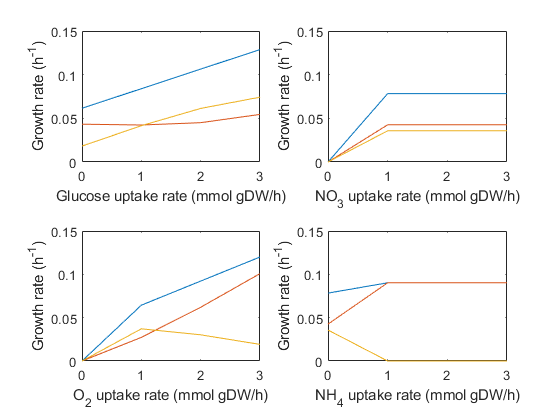


 %Pair-wise robustness analysis
 model=mergeModelm;
BOFs=find(model.c);
 units={' uptake rate (mmol gDW/h)'};
 solutionLna = optimizeCbModel(model,'max','one');
 Enzymes2={'EX_glc__A_[smp]';'EX_no3_[smp]';'EX_o2_[smp]';'EX_nh4_[smp]'};
Enzymes={'Glucose_ ';'NO_3 ';'O_2 ';'NH_4 '};
mayaAuto=[];x=[];mayaAuto1=[];mayaAuto2=[];
figure
for j=1:numel(Enzymes2)
    model=CoModels{1,6};
    solutionLna = optimizeCbModel(model,'max','one');
    for i=1:4
        valor=i-1;
    model=changeRxnBounds(model,Enzymes2{j},-valor,'l'); 
    solutionLna = optimizeCbModel(model,'max','one');
    mayaAuto(i)=solutionLna.f;
        if mayaAuto(i)~=0
        mayaAuto1(i)=solutionLna.x(BOFs(1,1));
        mayaAuto2(i)=solutionLna.x(BOFs(2,1));
        end
    x(i)=valor;
    end
    subplot(numel(Enzymes2)/2,2,j)
    plot(x,mayaAuto)
    hold on
    plot(x,mayaAuto1)
    plot(x,mayaAuto2)
    hold off
   axis([0.0 3 -0.000 0.15])
    xlabel(strcat(Enzymes{j},units));
    ylabel('Growth rate (h^-^1)');  
    mayaAuto(:)='';x(:)='';mayaAuto1(:)='';mayaAuto2(:)='';
end

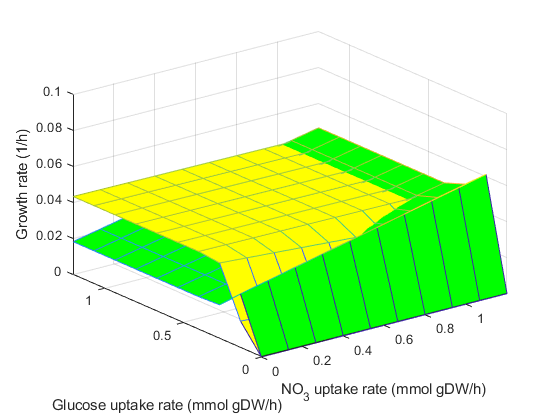

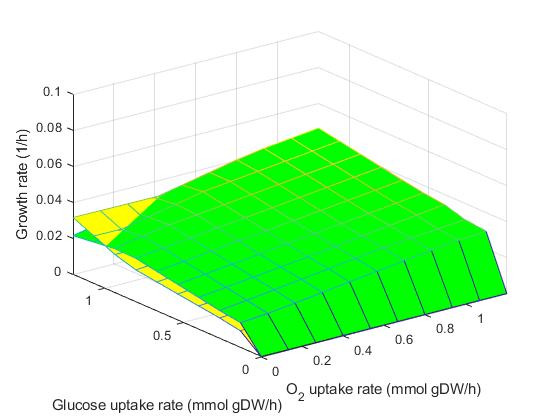

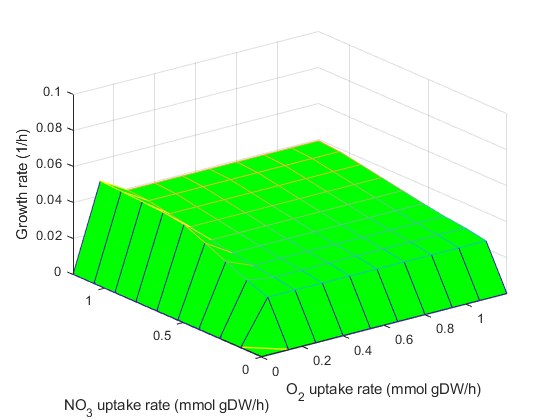

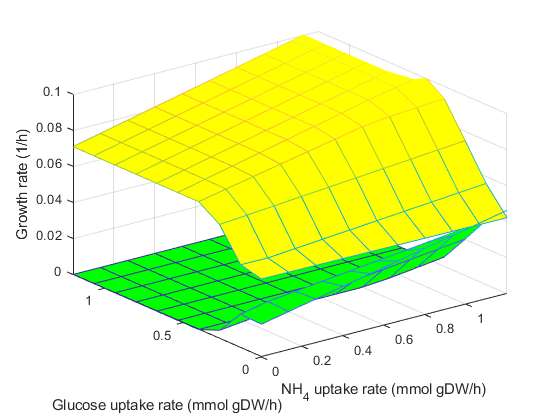

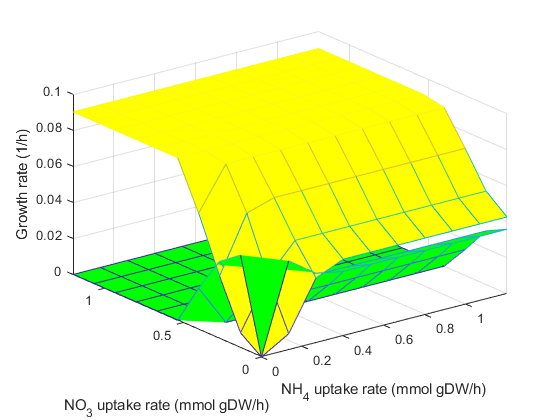

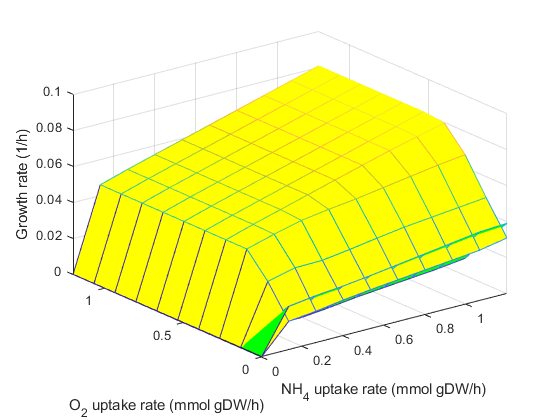


figure
Enzymes2={'EX_glc__A_[smp]';'EX_no3_[smp]';'EX_o2_[smp]';'EX_nh4_[smp]'};
Enzymes={'Glucose_ ';'NO_3 ';'O_2 ';'NH_4 '};

contF=0;
for d=1:numel(Enzymes2)
    
    for e=1:numel(Enzymes)
        mayaAuto(:)=[];x(:)=[];mayaAuto1(:)=[];mayaAuto2(:)=[];
    model=CoModels{1,6};
    solutionLna = optimizeCbModel(model,'max','one');
    cont=0;cont0=0;
    for i=1:10
        cont0=cont+1;
        for j=1:10
            valor=(i-1)/7.5;
            valor1=(j-1)/7.5;
            model=changeRxnBounds(model,{Enzymes2{d},Enzymes2{e}},[-valor -valor1],'l');
            solutionLna = optimizeCbModel(model);
                if solutionLna.f~=0
                  mayaAuto(i,j)=solutionLna.f;  
                    cont=cont+1;
                mayaAuto1(i,j)=solutionLna.x(BOFs(1,1));
                mayaAuto2(i,j)=solutionLna.x(BOFs(2,1));
                end
        x(i)=valor;
        y(j)=valor1;
        end
    cont=0;
    end
    
    if d>e
    contF=contF+1;
   % subplot(numel(Enzymes2),numel(Enzymes2),contF)
   figure
    b= mesh(x,y,mayaAuto1,'FaceColor','y');
    hold on
    c=mesh(x,y,mayaAuto2,'FaceColor','g');
    hold off
   axis([0.0 1.2 -0.000 1.2 0 0.1])
    xlabel(strcat(Enzymes{d},' uptake rate (mmol gDW/h)'));
    ylabel(strcat(Enzymes{e},' uptake rate (mmol gDW/h)'));
    zlabel('Growth rate (1/h)');
    end

    end
end

## **Nitrate availability and genetic drift stimulate community cooperation (Figure 3) **

**(A)**Experimental (E) and predicted (P) growth rates of the photobiont in monoculture and the lichen under nitrogen limitation. **(B) **Predicted shadow prices under different biomass compositions of the photobiont (monoculture, dark green, and coculture, light green). Metabolites limiting, increasing, and without effect on the growth rate are shown in blue, red, and white, respectively. Highlighted metabolites were tested experimentally. **(C)** Predicted metabolic exchange by the bionts over the course of growth.** (D)**Mycobiont knockouts (KOs) with enhanced growth phenotypes were experimentally tested, showing a significant increase of the community growth rate (*MIR1-, FUM1-, QCR7-*, and *OAR1-*) of up to 15% in comparison with the coculture of WT strains (**t-test, P=0.05). Growth rates were determined by cell counts over the course of growth for monoculture (M) and coculture (C) conditions. The mycobiont grew significantly faster under coculture conditions than in monoculture (*t-test, P=0.05). **(E)** The boxplots show the final biomass concentration measured by dry weight at the end of the experiments for all treatments. Orange boxplots are composed by the sum of experimentally determined biomass for the bionts under monoculture conditions and in blue the final biomass of the lichen. 

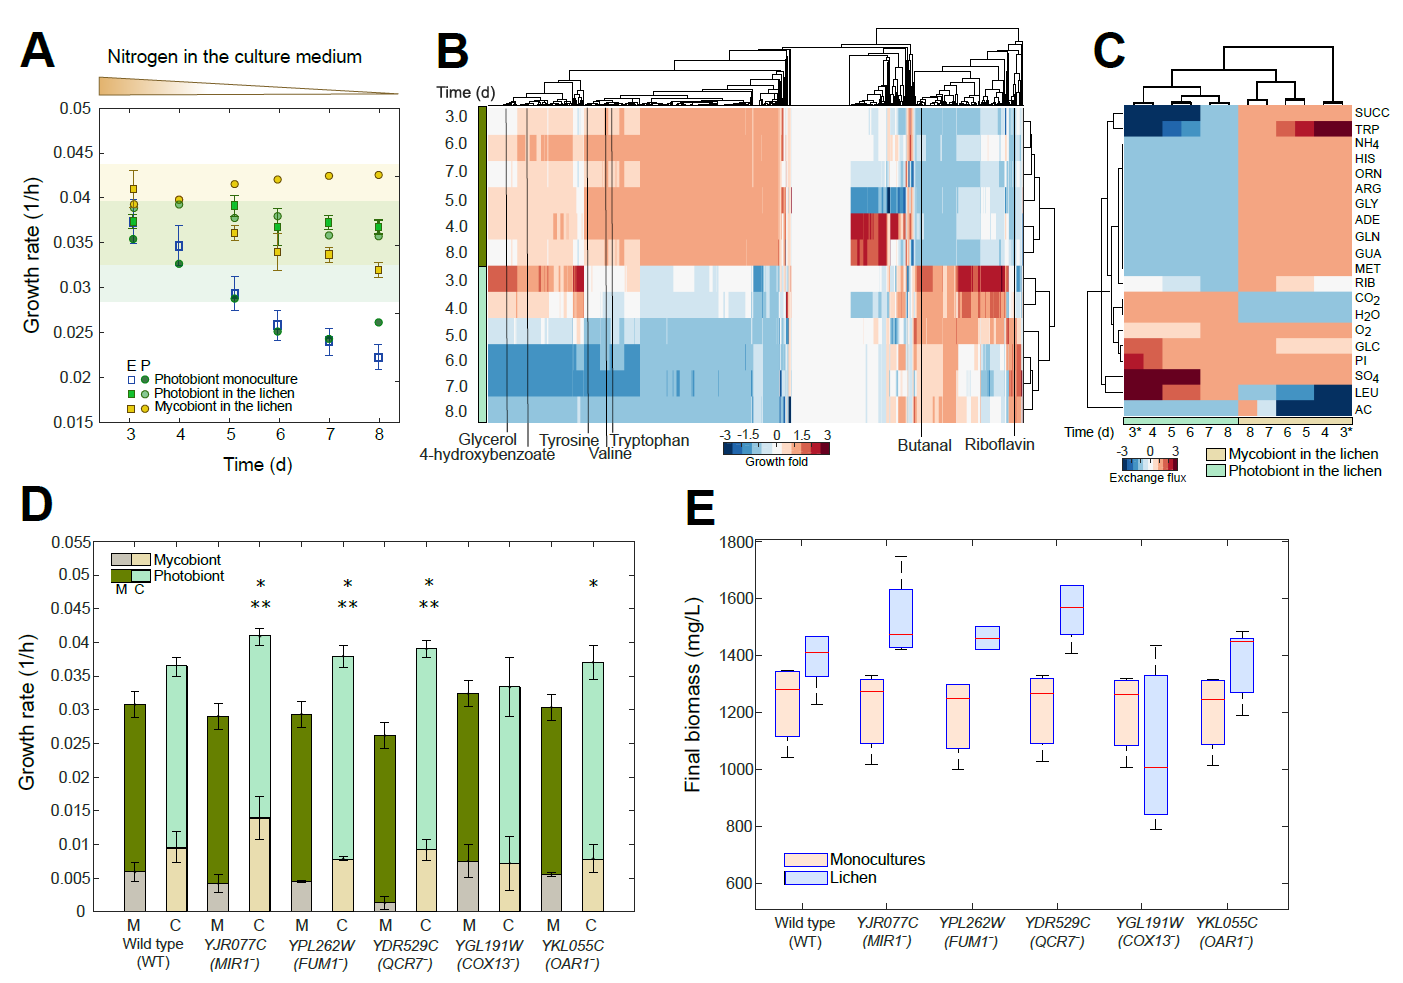

## **Predicted gene essentiality (fig. S9)**

**(A) **The bar plots depict the number of genes with lethal phenotypes as well as the number of genes improving and reducing the growth rate. Simulations were performed for all biomass compositions. Coculture predictions showed that single KOs resulted in increasing growth rate phenotypes for *C. vulgaris* (5-6% of the total genes) at all biomass compositions. KOs associated with reactions in the amino acid metabolism, pigments biosynthesis, central carbon and energy metabolisms of *C. vulgaris* were predicted to increase the growth rate of the lichen.One third of these reactions are located in the cytoplasm and the others in the chloroplast, glyoxysome, and mitochondria. However, up to 4% of the genes of *S. cerevisiae* resulted in improved phenotypes under nitrogen depletion (time 7 and 8 days). These reactions were associated with the metabolism and one transport reaction and located in the mitochondria (see tables S6-S10). Data represent mean ±SD. **(B)** The biomass compositions of *C. vulgaris* along the course of growth under photoautotrophy (*7*) were used to constrain *i*CZ-CvSc(1748) (Supplemental File 1). Each biomass composition accounts for over one hundred metabolites categorized as proteins, nucleotides, lipids, pigments, and carbohydrates (*1*). The total elemental biomass composition was calculated using the molecular formula of the respective metabolite.** (C)** Experimental (E) and predicted (P) growth rates for the photobiont in monoculture and the photobiont and mycobiont in mono- and coculture at the different biomass compositions.

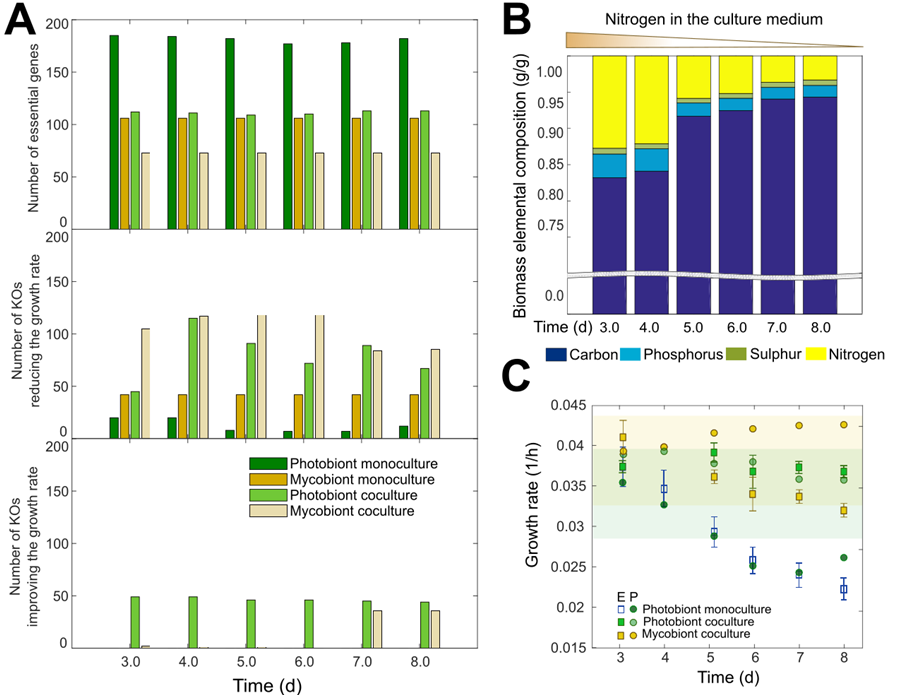

%Shadow prices
%Generating the solutions
model=CoModels{1,1};
BOFs=find(model.c);
solutionCo={};solutionCoS={};solutionA={};
for j=1:numel(CoModels)
    model=CoModels{1,j};
    model2=ModelPA{1,j};
    solutionCo{j}=optimizeCbModel(model);
    solutionCoS{1,j}=solutionCo{j}.x(BOFs(1));
    solutionCoS{2,j}=solutionCo{j}.x(BOFs(2));
    solutionA{j}=optimizeCbModel(model2);
end
solutionY=optimizeCbModel(modelSc2);
model=ModelPA{1,1};
Data=[];cont=0;
for i=1:numel(model.mets)
    model.mets{i}=strcat(model.mets{i},'_A');
    ind=strmatch(model.mets{i},CoModels{1,1}.mets,'exact');
    if ~isempty(ind)
        cont=cont+1;
        Data(i,:)= horzcat(solutionCo{1,1}.y(ind),solutionCo{1,2}.y(ind),solutionCo{1,3}.y(ind),solutionCo{1,4}.y(ind),solutionCo{1,5}.y(ind),solutionCo{1,6}.y(ind));
    else
            model.mets{i}=strcat(model.mets{i}(1:end-2),'_[smp]');
            ind=strmatch(model.mets{i},CoModels{1,1}.mets,'exact');
            if ~isempty(ind)
            cont=cont+1;
            Data(i,:)= horzcat(solutionCo{1,1}.y(ind),solutionCo{1,2}.y(ind),solutionCo{1,3}.y(ind),solutionCo{1,4}.y(ind),solutionCo{1,5}.y(ind),solutionCo{1,6}.y(ind));
            else
                   model.mets{i}=strcat(model.mets{i}(1:end-8),'_[smp]');
                ind=strmatch(model.mets{i},CoModels{1,1}.mets,'exact');
                if ~isempty(ind)
                cont=cont+1;
                Data(i,:)= horzcat(solutionCo{1,1}.y(ind),solutionCo{1,2}.y(ind),solutionCo{1,3}.y(ind),solutionCo{1,4}.y(ind),solutionCo{1,5}.y(ind),solutionCo{1,6}.y(ind));
                else
                    i
                end
          end
    end
end


%Figure 3B
Times={'3.0','4.0','5.0','6.0','7.0','8.0','3.0','4.0','5.0','6.0','7.0','8.0'};
C1 = horzcat(solutionA{1,1}.y,solutionA{1,2}.y,solutionA{1,3}.y,solutionA{1,4}.y,solutionA{1,5}.y,solutionA{1,6}.y);

C1 =    -0.0021   -0.0020   -0.0017   -0.0015   -0.0015   -0.0016
   -0.0029   -0.0026   -0.0041   -0.0035   -0.0034   -0.0037
   -0.0029   -0.0026   -0.0041   -0.0035   -0.0034   -0.0037
   -0.0021   -0.0020   -0.0017   -0.0015   -0.0015   -0.0016
   -0.0332   -0.0306   -0.0253   -0.0220   -0.0213   -0.0229
   -0.0339   -0.0313   -0.0276   -0.0240   -0.0232   -0.0250
   -0.1950   -0.1798   -0.1726   -0.1503   -0.1452   -0.1563
   -0.2100   -0.1936   -0.1848   -0.1609   -0.1555   -0.1674
   -0.2089   -0.1926   -0.1848   -0.1609   -0.1555   -0.1674
   -0.2089   -0.1926   -0.1848   -0.1609   -0.1555   -0.1674


C = horzcat(C1,Data)

C =    -0.0021   -0.0020   -0.0017   -0.0015   -0.0015   -0.0016   -0.0019   -0.0019   -0.0019   -0.0020   -0.0019   -0.0019
   -0.0029   -0.0026   -0.0041   -0.0035   -0.0034   -0.0037   -0.0019   -0.0019   -0.0019   -0.0020   -0.0019   -0.0113
   -0.0029   -0.0026   -0.0041   -0.0035   -0.0034   -0.0037   -0.0019   -0.0019   -0.0019   -0.0020   -0.0019   -0.0113
   -0.0021   -0.0020   -0.0017   -0.0015   -0.0015   -0.0016   -0.0019   -0.0019   -0.0019   -0.0020   -0.0019   -0.0019
   -0.0332   -0.0306   -0.0253   -0.0220   -0.0213   -0.0229   -0.0377   -0.0387   -0.0385   -0.0390   -0.0378   -0.0378
   -0.0339   -0.0313   -0.0276   -0.0240   -0.0232   -0.0250   -0.0377   -0.0387   -0.0385   -0.0390   -0.0378   -0.0472
   -0.1950   -0.1798   -0.1726   -0.1503   -0.1452   -0.1563   -0.0922   -0.1003   -0.0985   -0.1030   -0.0925   -0.0925
   -0.2100   -0.1936   -0.1848   -0.1609   -0.1555   -0.1674   -0.1330   -0.1413   -0.1395   -0.1440   -0.1334   -0.1333
   -0.2089   -0.1926   -0.18

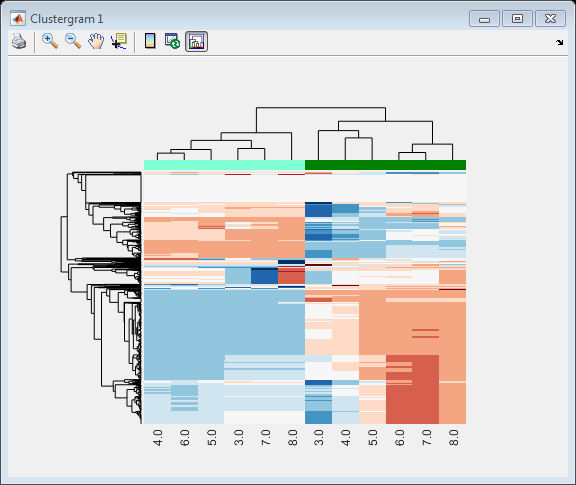

cgo = clustergram(C,'Colormap',redbluecmap,'Standardize','Row','ColumnLabels',Times);
cm = struct('GroupNumber',{8,10},'Annotation',{'Time1','Time2'},...
     'Color',{[0.5 1 0.83],[0 0.5 0]});
set(cgo, 'ColumnGroupMarker',cm)

%The function single gene deletion comparison (singleGeneDeletionComparison) 
% %Compare models gene essentiallity in coculture and monoculture. 
[A_SingleDel D_SingleDel C_SingleDelD C_SingleDelA] = singleGeneDeletionComparison(ModelPA{1,1},modelSc2,CoModels{1,1}); 

FBAsolA = struct with fields:
           x: [2294×1 double]
           f: 0.0355
           y: [1770×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.0480


FBAsolD = struct with fields:
           x: [1577×1 double]
           f: 0.0147
           y: [1226×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.0210


FBAsolCo = struct with fields:
           x: [3863×1 double]
           f: 0.0783
           y: [2964×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.1220


Subs =         1413
        1430


A_SingleDel = struct with fields:
    nonEffect: {634×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {634×1 cell}
       Effect: {185×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {634×1 cell}
       Effect: {185×1 cell}
      mEffect: {24×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {634×1 cell}
       Effect: {185×1 cell}
      mEffect: {24×1 cell}
          NaN: {0×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {634×1 cell}
       Effect: {185×1 cell}
      mEffect: {24×1 cell}
          NaN: {0×1 cell}
      pEffect: {0×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}
          NaN: {37×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}
          NaN: {37×1 cell}
      pEffect: {0×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {355×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {355×1 cell}
       Effect: {417×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {355×1 cell}
       Effect: {417×1 cell}
      mEffect: {131×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {355×1 cell}
       Effect: {417×1 cell}
      mEffect: {131×1 cell}
          NaN: {0×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {355×1 cell}
       Effect: {417×1 cell}
      mEffect: {131×1 cell}
          NaN: {0×1 cell}
      pEffect: {2×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {342×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {342×1 cell}
       Effect: {375×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {342×1 cell}
       Effect: {375×1 cell}
      mEffect: {77×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {342×1 cell}
       Effect: {375×1 cell}
      mEffect: {77×1 cell}
          NaN: {0×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {342×1 cell}
       Effect: {375×1 cell}
      mEffect: {77×1 cell}
          NaN: {0×1 cell}
      pEffect: {49×1 cell}


[A_SingleDel2 D_SingleDel2 C_SingleDelD2 C_SingleDelA2] = singleGeneDeletionComparison(ModelPA{1,2},modelSc2,CoModels{1,2}); 

FBAsolA = struct with fields:
           x: [2294×1 double]
           f: 0.0327
           y: [1770×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.0410


FBAsolD = struct with fields:
           x: [1577×1 double]
           f: 0.0147
           y: [1226×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.0230


FBAsolCo = struct with fields:
           x: [3863×1 double]
           f: 0.0797
           y: [2964×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.1210


Subs =         1413
        1430


A_SingleDel = struct with fields:
    nonEffect: {638×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {638×1 cell}
       Effect: {185×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {638×1 cell}
       Effect: {185×1 cell}
      mEffect: {20×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {638×1 cell}
       Effect: {185×1 cell}
      mEffect: {20×1 cell}
          NaN: {0×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {638×1 cell}
       Effect: {185×1 cell}
      mEffect: {20×1 cell}
          NaN: {0×1 cell}
      pEffect: {0×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}
          NaN: {37×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}
          NaN: {37×1 cell}
      pEffect: {0×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {359×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {359×1 cell}
       Effect: {417×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {359×1 cell}
       Effect: {417×1 cell}
      mEffect: {128×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {359×1 cell}
       Effect: {417×1 cell}
      mEffect: {128×1 cell}
          NaN: {0×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {359×1 cell}
       Effect: {417×1 cell}
      mEffect: {128×1 cell}
          NaN: {0×1 cell}
      pEffect: {'YPL262W'}


C_SingleDelA = struct with fields:
    nonEffect: {343×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {343×1 cell}
       Effect: {374×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {343×1 cell}
       Effect: {374×1 cell}
      mEffect: {77×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {343×1 cell}
       Effect: {374×1 cell}
      mEffect: {77×1 cell}
          NaN: {0×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {343×1 cell}
       Effect: {374×1 cell}
      mEffect: {77×1 cell}
          NaN: {0×1 cell}
      pEffect: {49×1 cell}


[A_SingleDel3 D_SingleDel3 C_SingleDelD3 C_SingleDelA3] = singleGeneDeletionComparison(ModelPA{1,3},modelSc2,CoModels{1,3}); 

FBAsolA = struct with fields:
           x: [2294×1 double]
           f: 0.0289
           y: [1770×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.0660


FBAsolD = struct with fields:
           x: [1577×1 double]
           f: 0.0147
           y: [1226×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.0210


FBAsolCo = struct with fields:
           x: [3863×1 double]
           f: 0.0794
           y: [2964×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.1150


Subs =         1413
        1430


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {182×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {182×1 cell}
      mEffect: {6×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {182×1 cell}
      mEffect: {6×1 cell}
          NaN: {0×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {182×1 cell}
      mEffect: {6×1 cell}
          NaN: {0×1 cell}
      pEffect: {0×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}
          NaN: {37×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}
          NaN: {37×1 cell}
      pEffect: {0×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {133×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {133×1 cell}
       Effect: {417×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {133×1 cell}
       Effect: {417×1 cell}
      mEffect: {354×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {133×1 cell}
       Effect: {417×1 cell}
      mEffect: {354×1 cell}
          NaN: {0×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {133×1 cell}
       Effect: {417×1 cell}
      mEffect: {354×1 cell}
          NaN: {0×1 cell}
      pEffect: {'YPL262W'}


C_SingleDelA = struct with fields:
    nonEffect: {335×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {335×1 cell}
       Effect: {373×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {335×1 cell}
       Effect: {373×1 cell}
      mEffect: {89×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {335×1 cell}
       Effect: {373×1 cell}
      mEffect: {89×1 cell}
          NaN: {0×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {335×1 cell}
       Effect: {373×1 cell}
      mEffect: {89×1 cell}
          NaN: {0×1 cell}
      pEffect: {46×1 cell}


[A_SingleDel4 D_SingleDel4 C_SingleDelD4 C_SingleDelA4] = singleGeneDeletionComparison(ModelPA{1,4},modelSc2,CoModels{1,4}); 

FBAsolA = struct with fields:
           x: [2294×1 double]
           f: 0.0251
           y: [1770×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.0420


FBAsolD = struct with fields:
           x: [1577×1 double]
           f: 0.0147
           y: [1226×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.0220


FBAsolCo = struct with fields:
           x: [3863×1 double]
           f: 0.0801
           y: [2964×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.1120


Subs =         1413
        1430


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {178×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {178×1 cell}
      mEffect: {6×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {178×1 cell}
      mEffect: {6×1 cell}
          NaN: {0×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {178×1 cell}
      mEffect: {6×1 cell}
          NaN: {0×1 cell}
      pEffect: {0×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}
          NaN: {37×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}
          NaN: {37×1 cell}
      pEffect: {0×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {350×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {350×1 cell}
       Effect: {417×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {350×1 cell}
       Effect: {417×1 cell}
      mEffect: {138×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {350×1 cell}
       Effect: {417×1 cell}
      mEffect: {138×1 cell}
          NaN: {0×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {350×1 cell}
       Effect: {417×1 cell}
      mEffect: {138×1 cell}
          NaN: {0×1 cell}
      pEffect: {0×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {349×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {349×1 cell}
       Effect: {375×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {349×1 cell}
       Effect: {375×1 cell}
      mEffect: {73×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {349×1 cell}
       Effect: {375×1 cell}
      mEffect: {73×1 cell}
          NaN: {0×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {349×1 cell}
       Effect: {375×1 cell}
      mEffect: {73×1 cell}
          NaN: {0×1 cell}
      pEffect: {46×1 cell}


[A_SingleDel5 D_SingleDel5 C_SingleDelD5 C_SingleDelA5] = singleGeneDeletionComparison(ModelPA{1,5},modelSc2,CoModels{1,5}); 

FBAsolA = struct with fields:
           x: [2294×1 double]
           f: 0.0243
           y: [1770×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.0610


FBAsolD = struct with fields:
           x: [1577×1 double]
           f: 0.0147
           y: [1226×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.0230


FBAsolCo = struct with fields:
           x: [3863×1 double]
           f: 0.0783
           y: [2964×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.1210


Subs =         1413
        1430


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {178×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {178×1 cell}
      mEffect: {6×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {178×1 cell}
      mEffect: {6×1 cell}
          NaN: {0×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {178×1 cell}
      mEffect: {6×1 cell}
          NaN: {0×1 cell}
      pEffect: {0×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}
          NaN: {37×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}
          NaN: {37×1 cell}
      pEffect: {0×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {377×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {377×1 cell}
       Effect: {417×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {377×1 cell}
       Effect: {417×1 cell}
      mEffect: {75×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {377×1 cell}
       Effect: {417×1 cell}
      mEffect: {75×1 cell}
          NaN: {0×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {377×1 cell}
       Effect: {417×1 cell}
      mEffect: {75×1 cell}
          NaN: {0×1 cell}
      pEffect: {36×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {135×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {135×1 cell}
       Effect: {377×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {135×1 cell}
       Effect: {377×1 cell}
      mEffect: {286×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {135×1 cell}
       Effect: {377×1 cell}
      mEffect: {286×1 cell}
          NaN: {0×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {135×1 cell}
       Effect: {377×1 cell}
      mEffect: {286×1 cell}
          NaN: {0×1 cell}
      pEffect: {45×1 cell}


[A_SingleDel6 D_SingleDel6 C_SingleDelD6 C_SingleDelA6] = singleGeneDeletionComparison(ModelPA{1,6},modelSc2,CoModels{1,6}); 

FBAsolA = struct with fields:
           x: [2294×1 double]
           f: 0.0262
           y: [1770×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.0690


FBAsolD = struct with fields:
           x: [1577×1 double]
           f: 0.0147
           y: [1226×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.0220


FBAsolCo = struct with fields:
           x: [3863×1 double]
           f: 0.0783
           y: [2964×1 double]
           w: []
        stat: 1
    origStat: -99
      solver: 'gurobi5'
        time: 0.1160


Subs =         1413
        1430


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {182×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {182×1 cell}
      mEffect: {6×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {182×1 cell}
      mEffect: {6×1 cell}
          NaN: {0×1 cell}


A_SingleDel = struct with fields:
    nonEffect: {655×1 cell}
       Effect: {182×1 cell}
      mEffect: {6×1 cell}
          NaN: {0×1 cell}
      pEffect: {0×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}
          NaN: {37×1 cell}


D_SingleDel = struct with fields:
    nonEffect: {741×1 cell}
       Effect: {108×1 cell}
      mEffect: {19×1 cell}
          NaN: {37×1 cell}
      pEffect: {0×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {369×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {369×1 cell}
       Effect: {417×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {369×1 cell}
       Effect: {417×1 cell}
      mEffect: {83×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {369×1 cell}
       Effect: {417×1 cell}
      mEffect: {83×1 cell}
          NaN: {0×1 cell}


C_SingleDelD = struct with fields:
    nonEffect: {369×1 cell}
       Effect: {417×1 cell}
      mEffect: {83×1 cell}
          NaN: {0×1 cell}
      pEffect: {36×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {324×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {324×1 cell}
       Effect: {377×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {324×1 cell}
       Effect: {377×1 cell}
      mEffect: {98×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {324×1 cell}
       Effect: {377×1 cell}
      mEffect: {98×1 cell}
          NaN: {0×1 cell}


C_SingleDelA = struct with fields:
    nonEffect: {324×1 cell}
       Effect: {377×1 cell}
      mEffect: {98×1 cell}
          NaN: {0×1 cell}
      pEffect: {44×1 cell}


%Looking at data by time point % % 
C_SingleDelA.rEffect=intersect(C_SingleDelA.Effect,A_SingleDel.Effect) 

C_SingleDelA = struct with fields:
    nonEffect: {342×1 cell}
       Effect: {375×1 cell}
      mEffect: {77×1 cell}
          NaN: {0×1 cell}
      pEffect: {49×1 cell}
      grRatio: [843×1 double]
      rEffect: {112×1 cell}


C_SingleDelA2.rEffect=intersect(C_SingleDelA2.Effect,A_SingleDel2.Effect) 

C_SingleDelA2 = struct with fields:
    nonEffect: {343×1 cell}
       Effect: {374×1 cell}
      mEffect: {77×1 cell}
          NaN: {0×1 cell}
      pEffect: {49×1 cell}
      grRatio: [843×1 double]
      rEffect: {111×1 cell}


C_SingleDelA3.rEffect=intersect(C_SingleDelA3.Effect,A_SingleDel3.Effect) 

C_SingleDelA3 = struct with fields:
    nonEffect: {335×1 cell}
       Effect: {373×1 cell}
      mEffect: {89×1 cell}
          NaN: {0×1 cell}
      pEffect: {46×1 cell}
      grRatio: [843×1 double]
      rEffect: {109×1 cell}


C_SingleDelA4.rEffect=intersect(C_SingleDelA4.Effect,A_SingleDel4.Effect) 

C_SingleDelA4 = struct with fields:
    nonEffect: {349×1 cell}
       Effect: {375×1 cell}
      mEffect: {73×1 cell}
          NaN: {0×1 cell}
      pEffect: {46×1 cell}
      grRatio: [843×1 double]
      rEffect: {111×1 cell}


C_SingleDelA5.rEffect=intersect(C_SingleDelA5.Effect,A_SingleDel5.Effect) 

C_SingleDelA5 = struct with fields:
    nonEffect: {135×1 cell}
       Effect: {377×1 cell}
      mEffect: {286×1 cell}
          NaN: {0×1 cell}
      pEffect: {45×1 cell}
      grRatio: [843×1 double]
      rEffect: {113×1 cell}


C_SingleDelA6.rEffect=intersect(C_SingleDelA6.Effect,A_SingleDel6.Effect) 

C_SingleDelA6 = struct with fields:
    nonEffect: {324×1 cell}
       Effect: {377×1 cell}
      mEffect: {98×1 cell}
          NaN: {0×1 cell}
      pEffect: {44×1 cell}
      grRatio: [843×1 double]
      rEffect: {113×1 cell}


C_SingleDelD.rEffect=intersect(C_SingleDelD.Effect,D_SingleDel.Effect) 

C_SingleDelD = struct with fields:
    nonEffect: {355×1 cell}
       Effect: {417×1 cell}
      mEffect: {131×1 cell}
          NaN: {0×1 cell}
      pEffect: {2×1 cell}
      grRatio: [905×1 double]
      rEffect: {73×1 cell}


C_SingleDelD2.rEffect=intersect(C_SingleDelD2.Effect,D_SingleDel2.Effect) 

C_SingleDelD2 = struct with fields:
    nonEffect: {359×1 cell}
       Effect: {417×1 cell}
      mEffect: {128×1 cell}
          NaN: {0×1 cell}
      pEffect: {'YPL262W'}
      grRatio: [905×1 double]
      rEffect: {73×1 cell}


C_SingleDelD3.rEffect=intersect(C_SingleDelD3.Effect,D_SingleDel3.Effect) 

C_SingleDelD3 = struct with fields:
    nonEffect: {133×1 cell}
       Effect: {417×1 cell}
      mEffect: {354×1 cell}
          NaN: {0×1 cell}
      pEffect: {'YPL262W'}
      grRatio: [905×1 double]
      rEffect: {73×1 cell}


C_SingleDelD4.rEffect=intersect(C_SingleDelD4.Effect,D_SingleDel4.Effect) 

C_SingleDelD4 = struct with fields:
    nonEffect: {350×1 cell}
       Effect: {417×1 cell}
      mEffect: {138×1 cell}
          NaN: {0×1 cell}
      pEffect: {0×1 cell}
      grRatio: [905×1 double]
      rEffect: {73×1 cell}


C_SingleDelD5.rEffect=intersect(C_SingleDelD5.Effect,D_SingleDel5.Effect) 

C_SingleDelD5 = struct with fields:
    nonEffect: {377×1 cell}
       Effect: {417×1 cell}
      mEffect: {75×1 cell}
          NaN: {0×1 cell}
      pEffect: {36×1 cell}
      grRatio: [905×1 double]
      rEffect: {73×1 cell}


C_SingleDelD6.rEffect=intersect(C_SingleDelD6.Effect,D_SingleDel6.Effect) 

C_SingleDelD6 = struct with fields:
    nonEffect: {369×1 cell}
       Effect: {417×1 cell}
      mEffect: {83×1 cell}
          NaN: {0×1 cell}
      pEffect: {36×1 cell}
      grRatio: [905×1 double]
      rEffect: {73×1 cell}


EffectNum=[numel(A_SingleDel.Effect),numel(A_SingleDel2.Effect), numel(A_SingleDel3.Effect),numel(A_SingleDel4.Effect),numel(A_SingleDel5.Effect),numel(A_SingleDel6.Effect);... 
    numel(D_SingleDel.Effect), numel(D_SingleDel2.Effect), numel(D_SingleDel3.Effect), numel(D_SingleDel4.Effect), numel(D_SingleDel5.Effect), numel(D_SingleDel6.Effect);... 
    numel(C_SingleDelA.rEffect),numel(C_SingleDelA2.rEffect), numel(C_SingleDelA3.rEffect), numel(C_SingleDelA4.rEffect), numel(C_SingleDelA5.rEffect), numel(C_SingleDelA6.rEffect);... 
    numel(C_SingleDelD.rEffect), numel(C_SingleDelD2.rEffect), numel(C_SingleDelD3.rEffect),numel(C_SingleDelD4.rEffect),numel(C_SingleDelD5.rEffect),numel(C_SingleDelD6.rEffect)]; 
mEffectNum=[numel(A_SingleDel.mEffect),numel(A_SingleDel2.mEffect), numel(A_SingleDel3.mEffect),numel(A_SingleDel4.mEffect),numel(A_SingleDel5.mEffect),numel(A_SingleDel6.mEffect);... 
    numel(D_SingleDel.mEffect), numel(D_SingleDel2.mEffect), numel(D_SingleDel3.mEffect), numel(D_SingleDel4.mEffect), numel(D_SingleDel5.mEffect), numel(D_SingleDel6.mEffect);... 
    numel(C_SingleDelA.mEffect),numel(C_SingleDelA2.mEffect), numel(C_SingleDelA3.mEffect), numel(C_SingleDelA4.mEffect), numel(C_SingleDelA5.mEffect), numel(C_SingleDelA6.mEffect);... 
    numel(C_SingleDelD.mEffect), numel(C_SingleDelD2.mEffect), numel(C_SingleDelD3.mEffect),numel(C_SingleDelD4.mEffect),numel(C_SingleDelD5.mEffect),numel(C_SingleDelD6.mEffect)]; 
pEffectNum=[numel(A_SingleDel.pEffect),numel(A_SingleDel2.pEffect), numel(A_SingleDel3.pEffect),numel(A_SingleDel4.pEffect),numel(A_SingleDel5.pEffect),numel(A_SingleDel6.pEffect);... 
    numel(D_SingleDel.pEffect), numel(D_SingleDel2.pEffect), numel(D_SingleDel3.pEffect), numel(D_SingleDel4.pEffect), numel(D_SingleDel5.pEffect), numel(D_SingleDel6.pEffect);... 
    numel(C_SingleDelA.pEffect),numel(C_SingleDelA2.pEffect), numel(C_SingleDelA3.pEffect), numel(C_SingleDelA4.pEffect), numel(C_SingleDelA5.pEffect), numel(C_SingleDelA6.pEffect);... 
    numel(C_SingleDelD.pEffect), numel(C_SingleDelD2.pEffect), numel(C_SingleDelD3.pEffect),numel(C_SingleDelD4.pEffect),numel(C_SingleDelD5.pEffect),numel(C_SingleDelD6.pEffect)]; 
Time={'3.0';'4.0';'5,0';'6.0';'7.0';'8.0'}; 
figure 
subplot(3,1,1) 
ax=bar(transpose(EffectNum)) 

ax =   1×4 Bar array:

    Bar    Bar    Bar    Bar


xlabel(sprintf('Biomass composition')); 
ylabel(sprintf('Number of essential genes')); 
axis([0 7 0 200]) 
set(gca,'xticklabel',Time) 
legend(ax,'Photobiont monoculture','Mycobiont monoculture','Photobiont lichen','Mycobiont Lichen') 
subplot(3,1,2) 
ax=bar(transpose(mEffectNum)) 

ax =   1×4 Bar array:

    Bar    Bar    Bar    Bar


axis([0 7 0 200]) 
xlabel(sprintf('Biomass composition')); 
ylabel(sprintf('Number of KOs reducing the growth rate')); 
set(gca,'xticklabel',Time) 
legend(ax,'Photobiont monoculture','Mycobiont monoculture','Photobiont lichen','Mycobiont Lichen')  
subplot(3,1,3) 
ax=bar(transpose(pEffectNum)) 

ax =   1×4 Bar array:

    Bar    Bar    Bar    Bar


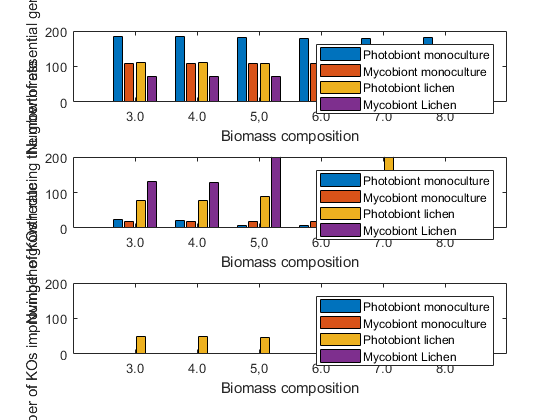

axis([0 7 0 200]) 
xlabel(sprintf('Biomass composition')); 
ylabel(sprintf('Number of KOs improving the growth rate')); 
set(gca,'xticklabel',Time) 
legend(ax,'Photobiont monoculture','Mycobiont monoculture','Photobiont lichen','Mycobiont Lichen') 

**Member-specific genomic capabilities help to overcome lethal genetic gaps in the community (Figure 4)** 

**(A)** Mutant strains of the mycobiont with lethal phenotypes (*RIB7-, PMI40-, SEC53-, PSA1-, ERG11-, GLN1-*) and mutants with nonlethal phenotypes (*CYS3-*and *OAR1-*) were essayed in coculture (C) and monoculture (M) conditions. Predicted growth phenotypes are shown with circles and experimental results with bar plots. **(B)** Photobiont growth rates were determined in coculture with each mutant strain of mycobiont KO and the wild type strain as control (WT). **(C) **Predicted metabolites exchanged for each pair condition, all fluxes were normalized by the predicted flux under wild type conditions. 

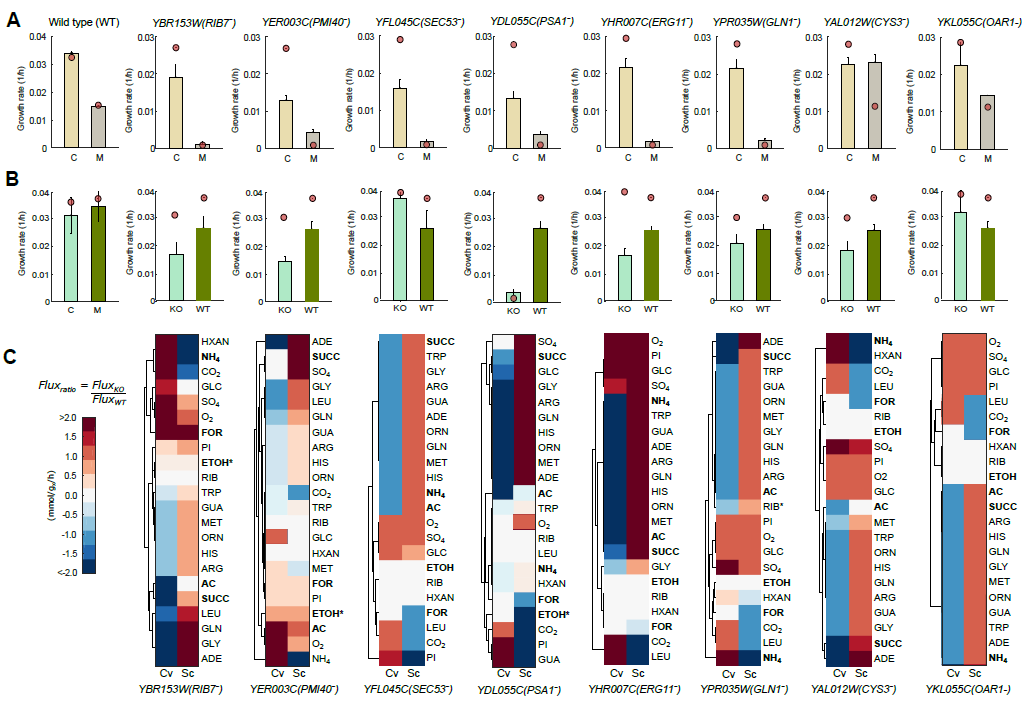

%Experimental data
Genes={'WT'; 'YBR153W';'YER003C';'YFL045C'; 'YDL055C'; 'YHR007C'; 'YPR035W'; 'YAL012W'; 'YKL055C'};
Genes2={'(WT)'; '(RIB7^-)' ;'(PMI40^-)';'(SEC53^-)';'(PSA1^-)';'(ERG11^-)';'(GLN1^-)';'(CYS3^-)';'(OAR1^-)'};
ChlorellaError=[0.004600	0.0050; 0.004100 0.0032500;0.001590	0.00187;0.002700	0.005560;0.002700	0.00180;0.003910	0.001370;0.004870	0.001370; 0.00230	0.00186; 0.0120	0.00186];
Chlorella=[0.031000	0.033;0.01800	0.024850;0.01490	0.022260;0.0378000	0.022940;0.003400	0.023480;0.01930	0.0246900;0.02140	0.024690;0.021000	0.025870;0.03090	0.025870];
Yeast=[0.0330	0.0150; 0.019130	0.00110; 0.012970	0.004350; 0.01600	0.001680; 0.013390	0.0035700; 0.021620	0.0094400; 0.021620	0.001710; 0.022540	0.023180; 0.022540	0.015830];
YeastError=[0.000120	0.001400; 0.003380	0.000250;0.001120	0.00060; 0.002170	0.00029; 0.001890	0.00084; 0.002620	0.00046; 0.002340	0.00634; 0.002240	0.00186; 0.007820	0.00162];

[C_grRatio,C_grRatio_coY,C_grRatio_coA,C_grRateKO,C_grRateWT,C_hasEffect,C_delRxns,~,~,C_fluxsolution1,C_modelos] = singleGeneDeletionCM(mergeModelm);

Subs =         1413
        1430


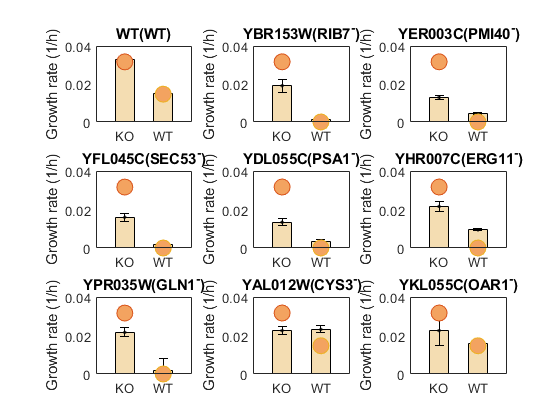

H =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.5000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2]
        YData: [0.0330 0.0150]

  Show all properties


H =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.5000
    FaceColor: [0.9583 0.8672 0.6992]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2]
        YData: [0.0191 0.0011]

  Show all properties


H =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.5000
    FaceColor: [0.9583 0.8672 0.6992]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2]
        YData: [0.0130 0.0043]

  Show all properties


H =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.5000
    FaceColor: [0.9583 0.8672 0.6992]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2]
        YData: [0.0160 0.0017]

  Show all properties


H =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.5000
    FaceColor: [0.9583 0.8672 0.6992]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2]
        YData: [0.0134 0.0036]

  Show all properties


H =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.5000
    FaceColor: [0.9583 0.8672 0.6992]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2]
        YData: [0.0216 0.0094]

  Show all properties


H =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.5000
    FaceColor: [0.9583 0.8672 0.6992]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2]
        YData: [0.0216 0.0017]

  Show all properties


H =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.5000
    FaceColor: [0.9583 0.8672 0.6992]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2]
        YData: [0.0225 0.0232]

  Show all properties


H =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.5000
    FaceColor: [0.9583 0.8672 0.6992]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2]
        YData: [0.0225 0.0158]

  Show all properties


[D_grRatio,D_grRateKO,D_grRateWT,D_delRxns,D_hasEffect,D_fluxSolution] = singleGeneDeletion(modelSc2);

figure
mycolor=[0.9583    0.8672    0.6992;0    0.5    0.0];
for i=1:numel(Genes)
    subplot(3,3,i)

H=bar(1:2,Yeast(i,:),0.5)
H(1).FaceColor = mycolor(1,:);
hold on
errorbar(1:2,Yeast(i,:),YeastError(i,:),'k.')

BOF=find(mergeModelm.c);
if i==1
    FBA=optimizeCbModel(mergeModelm);
    plot(1,FBA.x(BOF(1)),'o','MarkerSize',12,'MarkerFaceColor',[0.9542    0.6406    0.3750]);
else
   Ind=strmatch(Genes{i},mergeModelm.genes,'exact');
   FBA=optimizeCbModel(C_modelos{Ind});
   plot(1,FBA.x(BOF(1)),'o','MarkerSize',12,'MarkerFaceColor',[0.9542    0.6406    0.3750]);
end

if i==1
    FBA=optimizeCbModel(modelSc2);
    plot(2,FBA.f,'o','MarkerSize',12,'MarkerFaceColor',[0.9542    0.6406    0.3750]);
else
   Ind=strmatch(Genes{i},modelSc2.genes,'exact');
   plot(2,D_grRateKO(Ind),'o','MarkerSize',12,'MarkerFaceColor',[0.9542    0.6406    0.3750]);
end


L=strcat(Genes{i,1},Genes2{i,1});
title(L)
c = {'KO','WT'};
set(gca, 'XTick', 1:2, 'XTickLabel', c);
axis([0.25 2.75 0 0.04])
ylabel('Growth rate (1/h)');
end